# **Thermal Hydraulics Assignment 2, Q2**

## 0. Setup

Code initiation

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

## 1.  Problem Statement

Consider a slab with an initial temperature profile as shown below. Calculate the unsteady temperature profiles numerically as done in class, using $\frac{\alpha \;\Delta t}{{\left(\Delta x\right)}^2 }\;=\;0\ldotp 1$ and $0\ldotp 6$. Tabulate all the temperatures up to 10 time steps and plot the temperature profiles for each case.

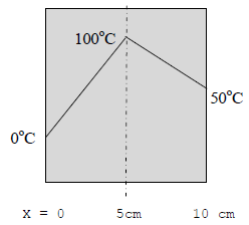

r = 0.1;
l = 10/100; % meters

We can get the initial temperature values if we express the left and right halves as linear equations. We will use $\Delta x=\frac{1}{100}$ meters.

delx = l/10;                % meters
s.t = zeros(1,l/delx + 1);  % note the + 1 --> need to include boundary temperatures
s.l = linspace(0,l,size(s.t, 2));
t.left = (100-0)/(l/2);
t.right = (50-100)/(l/2)

t = struct with fields:
     left: 2000
    right: -1000


s.t(1) = 0;
s.t(ceil(size(s.t, 2)/2)) = 100;
s.t(end) = 50;
for i = 2 : size(s.t, 2) - 1
    if i < ceil(size(s.t, 2) / 2)
    s.t(i) = t.left * s.l(i);
    elseif i > ceil(size(s.t, 2) / 2)
    s.t(i) = s.t(ceil(size(s.t, 2) / 2)) + (t.right * (s.l(i) - s.l(ceil(size(s.t, 2) / 2))));
    else
    disp("filled")
    end
end

filled


Plot to verify

clf
fig1 = figure('Name','Initial Slab Temperature Profile');

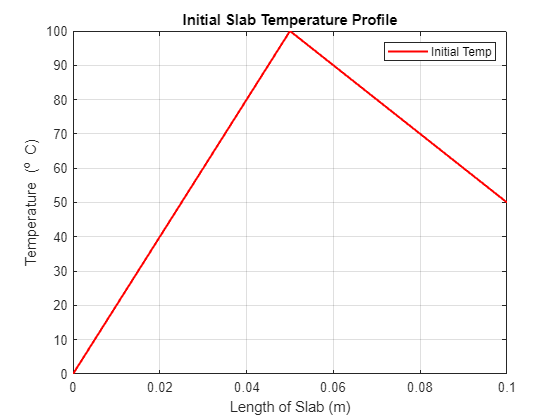

plot(s.l, s.t, LineWidth = 1.5, Color="r")
hold off
grid on
title('Initial Slab Temperature Profile')
xlabel('Length of Slab (m)')
ylabel('Temperature (^o C)')
legend('Initial Temp')

% xlim([0 0.1])
% ylim([-50 150])
ax1 = gca;

## 2. Numerical Solution (Explicit Method)

step = 10;
s.t(step + 1,1) = 0;
s.t(:,end) = 50;
for j = 1 : step
    for i = 2 : size(s.t, 2) - 1

        s.t(j+1,i) = s.t(j,i) + (r)*(s.t(j,i+1) - 2*s.t(j,i) + s.t(j,i-1));

    end
end
s.t

ans =          0   20.0000   40.0000   60.0000   80.0000  100.0000   90.0000   80.0000   70.0000   60.0000   50.0000
         0   20.0000   40.0000   60.0000   80.0000   97.0000   90.0000   80.0000   70.0000   60.0000   50.0000
         0   20.0000   40.0000   60.0000   79.7000   94.6000   89.7000   80.0000   70.0000   60.0000   50.0000
         0   20.0000   40.0000   59.9700   79.2200   92.6200   89.2200   79.9700   70.0000   60.0000   50.0000
         0   20.0000   39.9970   59.8980   78.6350   90.9400   88.6350   79.8980   69.9970   60.0000   50.0000
         0   19.9997   39.9874   59.7816   77.9918   89.4790   87.9918   79.7816   69.9874   59.9997   50.0000
         0   19.9985   39.9681   59.6232   77.3195   88.1816   87.3195   79.6232   69.9680   59.9985   50.0000
         0   19.9956   39.9366   59.4273   76.6361   87.0091   86.6361   79.4273   69.9366   59.9956   50.0000
         0   19.9901   39.8916   59.1991   75.9525   85.9345   85.9525   79.1991   69.8916   59.9901   50.

fig2 = figure('Name','Unsteady Slab Temperature Profile');

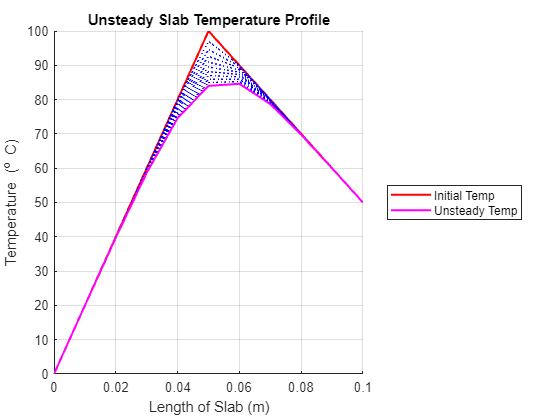

hold on
for i = 1 : size(s.t, 1)
    s.plot(i) = plot(s.l, s.t(i,:), LineWidth = 0.5, Color="b", LineStyle=":");
end

% alpha(s.plot(end), 0.1)
s.plot(1).LineStyle = "-";
s.plot(1).LineWidth = 1.5;
s.plot(1).Color = "r";
% for i = 2 : 10
%     s.plot(i).Color = [0.2 0.5 0.9 0.2]
% end
s.plot(end).LineStyle = "-";
s.plot(end).LineWidth = 1.5;
s.plot(end).Color = "magenta";

grid on
title('Unsteady Slab Temperature Profile')
xlabel('Length of Slab (m)')
ylabel('Temperature (^o C)')
legend([s.plot(1), s.plot(end)], {'Initial Temp', 'Unsteady Temp'}, Location="eastoutside")
hold off

% legend("Position", [0.44131,0.36746,0.42857,0.082143])
% xlim([0 0.1])
% ylim([-50 150])

## 3. For r = 0.6